# Calculate Factor of Safety for Given Wall Thickness

**Author:** Evan Olsen

**Date:** 02/02/2024

**Description: **Determines the factor of safety vs. engine length for given wall thickness data and temperature data for the interior and exterior wall. Averages the calculated stresses between the inner and outer walls and determines wall thickness given that average stress with the Hoop stress equation.

clc; clear; close all;

% Import Pre-calculated Variables in ANSYS. This will be a pain to do but
% the easiest method is to output pressure from your CFD simulation, and
% export wall temperature in terms of XYZ from your Transient Thermal
% simulation on the interior reference surface. Determine which data varies
% along your contour, typically the x-axis, and then import into matlab
% using the importtable() and table2array() functions. For reusability, you
% can save() to a .mat file.
load('P_x.mat')
load('0,15in,3s,ext.mat')
load('0,15in,3s,int.mat')
% Before importing your data, ensure that exported data from ANSYS is
% sorted from minimum to maximum x-values, and duplicate values are
% removed. My data was determined by rounding the x-values to the nearest
% four decimal places and removing duplicates.
% For example, this brought my data from 28,000 datapoints down to 350 due to
% the courseness of the calculated mesh on ANSYS Mechanical.

% Pre-calculated from parametric-liquid-engine script located at 
% https://github.com/RIT-Launch-Initiative/parametric-liquid-engine or
% other script.
load('R_x.mat')

% Analyzed Wall Thickness
t_wall_in = 0.15; % [in]
    t_wall_m = t_wall_in/39.37; % [m]

## **Determining Yield Strength Table for 304 Stainless Steel**

*Table 1. Allowable Stress Chart for 300* Series Stainless Steel*

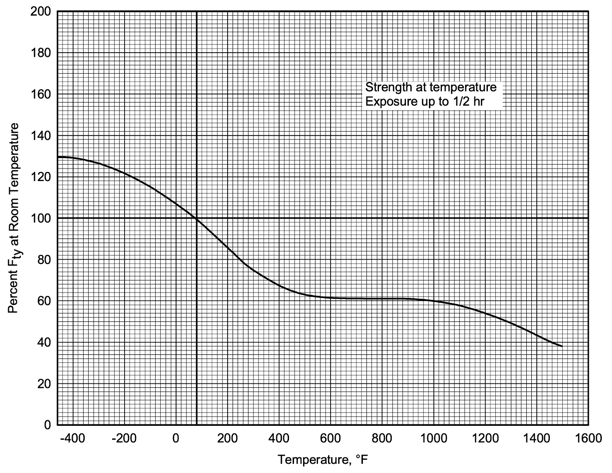

Source: [http://everyspec.com/FAA/FAA-General/DOT-FAA-AR-MMPDS-01-JAN2003_24102/,](http://everyspec.com/FAA/FAA-General/DOT-FAA-AR-MMPDS-01-JAN2003_24102/,)* Page 279*

% For 304 Stainless Steel - Yield Strength vs. Temperature
yield_strength_tbl = [215e6,210.7e6,184.9e6,159.1e6,146.2e6,135.45e6,133.3e6,131.15e6,131.15e6,131.15e6,129e6,124.7e6,116.1e6,107.5e6,92.45e6,81.7e6];
temp_tbl = [299.82,310.93,366.48,422.04,477.59,533.15,588.71,644.26,699.82,755.37,810.93,866.48,922.04,977.59,1033.15,1088.71];

## **Creating Fit Curves to Equalize the Matrix Lengths**

This section uses the cftool() curve fitting tool within MATLAB to create curve fits for the yield strength table, as well as using that function to equalize the matrix lengths. A linear curve fit is good enough for these purposes.

% Equalizes the lengths of one of the temperature matrices depending on
% which one is the shorter length. A linear fit cannot extend the length of
% a shorter vector, so some data is lost. Typically the matrices for inner
% and outer temperature are equal depending on the orthogonality of your
% generated mesh.
if(length(Temp_XYZ_Exterior(:,1)) < length(Temp_XYZ_Interior(:,1)))
    [fitresult_Temp,~] = createFit_Temp(Temp_XYZ_Interior(:,1),Temp_XYZ_Interior(:,2));
    for i=1:length(Temp_XYZ_Exterior(:,1))
        interiorTemp(i) = feval(fitresult_Temp,Temp_XYZ_Exterior(i,1));
    end  
    exteriorTemp = Temp_XYZ_Exterior(:,2)';
    L_x = Temp_XYZ_Exterior(:,1)';
else
    [fitresult_Temp,~] = createFit_Temp(Temp_XYZ_Exterior(:,1),Temp_XYZ_Exterior(:,2));
    for i=1:length(Temp_XYZ_Interior(:,1))
        exteriorTemp(i) = feval(fitresult_Temp,Temp_XYZ_Interior(i,1));
    end
    interiorTemp = Temp_XYZ_Interior(:,2)';
    L_x = Temp_XYZ_Interior(:,1)';
end

[fitresult_yield,~] = createFit_stress(temp_tbl,yield_strength_tbl);

% Evaluates the curve fit to determine the yield strength on the interior
% wall in terms of the engine length.
for i=1:length(interiorTemp)
    yield_strength_in(i) = feval(fitresult_yield,interiorTemp(i)); % [Pa]
end
for i=1:length(exteriorTemp)
    yield_strength_out(i) = feval(fitresult_yield,exteriorTemp(i)); % [Pa]
end

% Calculates the average yield strength between the outside and inside
% surfaces of the engine, to compensate for the fact that there is a
% temperature gradient from the inside surface to the outside. This method
% gives the most conservative answer compared to averaging the inner and
% outer wall temperatures, due to the increased change in yield strength
% per unit temperature.
yield_strength_avg = (yield_strength_in + yield_strength_out)./2; % [Pa]

% Creates a linear curve fit for the input pressure curve in order to
% equalize the lengths of the matrices with the inputted x-data within the
% wall temperature matrix.
[fitresult_pressure,~] = createFit_Pressure(P_x(:,1),P_x(:,2));
for j=1:length(L_x)
    internal_pressure(j) = feval(fitresult_pressure,L_x(j)); % [Pa]
end

% Creates a linear curve fit for the wall y-data to match the x-data in the
% wall temperature matrix.
[fitresult_wall,~] = createFit_wall(R_x(1,:),R_x(2,:));
for k=1:length(L_x)
    local_radius(k) = feval(fitresult_wall,L_x(k)); % [m]
end

## **Calculating Hoop Stress and Factor of Safety**

Hoop stress will be the most dominating stress on the engine throughout the burn, due to its cylindrical nature. Therefore, we can use the hoop stress formula for a cylinder to calculate the stress. Thermal stress is not accounted for in these calculations, because it is a compressive stress. Accounting for thermal stresses would reduce the equivalent stress on the system because it would act against the tensile hoop stresses.

To calculate the factor of safety, we can just divide our yield strength by the hoop stress at that location.

% Calculates hoop stress vs. engine length
H = (internal_pressure .* local_radius)./t_wall_m; % [Pa]
% Assume: Hoop stress (tensile) dominates over thermal stresses
% (compressive), this gives worst case scenario because equivalent stress
% would be lower than calculated if thermal stresses were considered.

% Calculates FOS from hoop stress
FOS = yield_strength_avg./H; % [-]

% To determine the external wall radius (outside contour), you add the
% minimum additional wall thickness and the base thickness to the local
% interior radius.
external_radius = local_radius + t_wall_m; % [m]

## **Graphical Representation**

wallThicknessPlot = figure('Name','FOS for Given Wall Thickness');

% Plot 1 of 4 - INTERNAL PRESSURE
subplot(4,1,1)
% Pressure on Internal Surface
plot(L_x,internal_pressure,'-b','LineWidth',1.2)
xlim([L_x(1),L_x(end)]);ylim([0 inf]);
grid on;
title('Internal Pressure vs. Length'); xlabel('$L_{e}$ $[m]$'); ylabel('$P_{int}$ $[Pa]$');

% Plot 2 of 4 - HOOP STRESS
subplot(4,1,2)
plot(L_x,H/1e6,'-g','LineWidth',1.2)
xlim([L_x(1),L_x(end)]);ylim([0 inf]);
grid on;
title('Hoop Stress vs. Length'); xlabel('$L_{e}$ $[m]$'); ylabel('$\sigma_{hoop}$ $[MPa]$');

% Plot 3 of 4 - FACTOR OF SAFETY
subplot(4,1,3)
% FOS vs. Engine Length
plot(L_x,FOS,'-r','LineWidth',1.2)
xlim([L_x(1),L_x(end)]);ylim([0 30]);
grid on;
title('F.O.S. vs. Length'); xlabel('$L_{e}$ $[m]$'); ylabel('FOS [-]');

% Plot 4 of 4 - ENGINE RADIUS
subplot(4,1,4)
hold on
% External Radius
plot(L_x*39.37,external_radius*39.37,'k','LineWidth',1.2)
% Internal Radius
plot(L_x*39.37,local_radius*39.37,'k','LineWidth',1.2)
xlim([L_x(1)*39.37,L_x(end)*39.37]);ylim([0 inf]);
grid on;
title('Wall Thickness vs. Length');xlabel('$L_{e}$ $[in]$'); ylabel('$R$ $[in]$');

yieldStrengthPlot = figure('Name','Allowable Stress Curves');

% Plot 1 of 3 - CURVE FIT
subplot(3,1,1)
% Yield Strength Curve Fit w/ Datapoints
plot(fitresult_yield,'k',temp_tbl,yield_strength_tbl,'-o')
xlim([temp_tbl(1) temp_tbl(end)]);ylim([0 inf])
title('Yield Strength Curve Fit');xlabel('$T_{wall}$ $[K]$'); ylabel('$\sigma_{yield}$ $[Pa]$');
grid on;
lgd_yieldStrengthFitPlot = legend('Raw Data','Curve Fit');
lgd_yieldStrengthFitPlot.Location = "southwest";

% Plot 2 of 3 - WALL TEMPERATURE
subplot(3,1,2)
hold on
% Interior Wall Temperature
plot(L_x,interiorTemp,'-r','LineWidth',1.2)
% Exterior Wall Temperature
plot(L_x,exteriorTemp,'-b','LineWidth',1.2)
ylim([0 inf]);
title('Wall Temperature vs. Length');xlabel('$L_{e}$ $[m]$');ylabel('$T_{wall}$ $[K]$');
grid on;
lgd_tempPlot = legend('$T_{int}$','$T_{ext}$');
lgd_tempPlot.Location = "northwest";


% Plot 3 of 3 - YIELD STRENGTH
subplot(3,1,3)
hold on
% Inner Surface Yield Strength
plot(L_x,yield_strength_in/1e6,'-b','LineWidth',1.2);
% Outer Surface Yield Strength
plot(L_x,yield_strength_out/1e6,'-r','LineWidth',1.2);
% Average Yield Strength Between Inner and Outer Surfaces
plot(L_x,yield_strength_avg/1e6,'-g','LineWidth',1.2);
ylim([0 inf]);
grid on;
title('Yield Strength vs. Length'); xlabel('$L_{e}$ $[m]$'); ylabel('$\sigma_{y}$ $[MPa]$');
lgd_yieldStrengthPlot = legend('Inside Wall $\sigma_{yield}$','Outside Wall $\sigma_{yield}$','Average $\sigma_{yield}$');
lgd_yieldStrengthPlot.Location = "southwest";

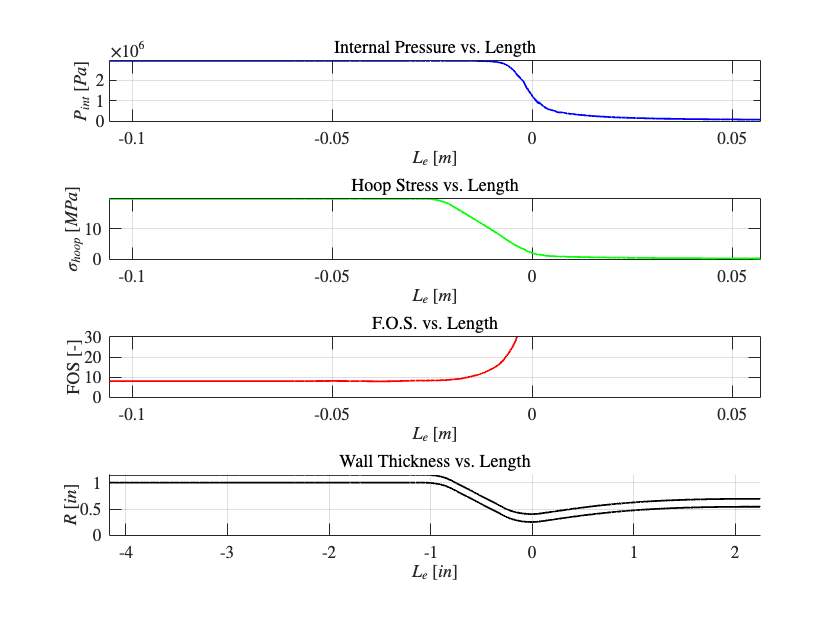

% Save Plot 1 as a PNG file
saveas(wallThicknessPlot,'wallThicknessPlot','png')

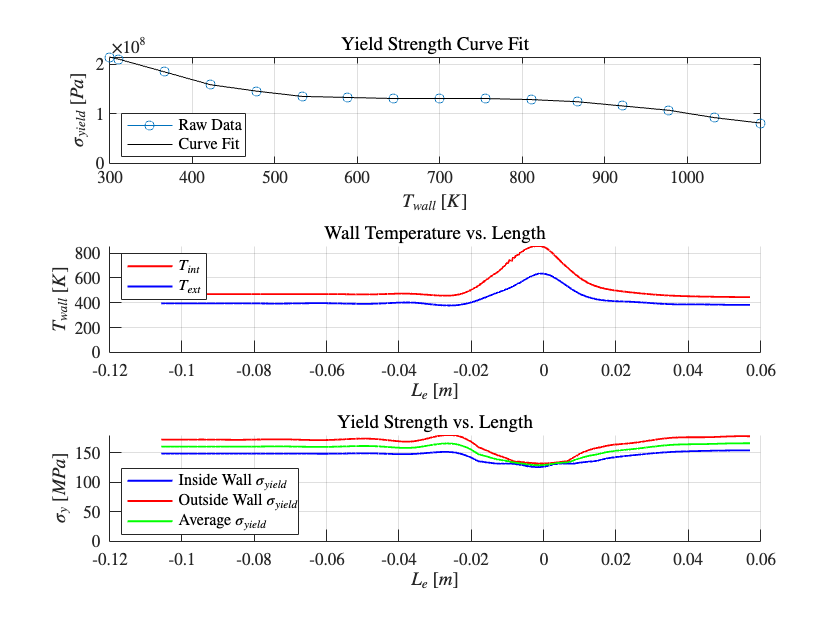

% Save Plot 2 as a PNG file
saveas(yieldStrengthPlot,'yieldStrengthPlot','png')

% Command Window Output
[~,throat_index] = min(local_radius);
throat_FOS = FOS(throat_index);
chamber_FOS = FOS(1);

fprintf('FOS @ Chamber = %.1f [-]\nFOS @ Throat = %.1f [-]\n',chamber_FOS,throat_FOS);

FOS @ Chamber = 8.1 [-]
FOS @ Throat = 61.6 [-]
